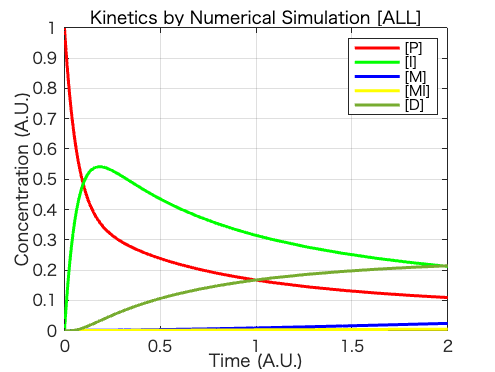

clc; clear; close all;



% Initial concentrations
P0 = 1;  % Initial concentration of P
I0 = 0.0;  % Initial concentration of I
M0 = 0.0;  % Initial concentration of M
MI0 = 0.0;  % Initial concentration of MI
D0 = 0.0;  % Initial concentration of D
y0 = [P0; I0; M0; MI0; D0];

% Time span
tspan = [0 2];  % From t=0 to t=10

% Solve ODEs using ode15s
[t, y] = ode15s(@(t, y) reaction_odes(t, y), tspan, y0);

% Plot results
figure;
plot(t, y(:,1), 'r-', 'LineWidth', 2); hold on;
plot(t, y(:,2), 'g-', 'LineWidth', 2);
plot(t, y(:,3), 'b-', 'LineWidth', 2);
plot(t, y(:,4), 'y-', 'LineWidth', 2);
plot(t, y(:,5), 'LineWidth', 2);
xlabel('Time (A.U.)');
ylabel('Concentration (A.U.)');
legend('[P]', '[I]','[M]','[MI]','[D]');
title('Kinetics by Numerical Simulation [ALL]');
grid on;

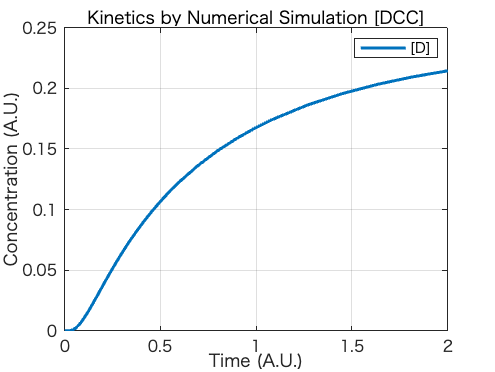


% Plot results
figure;
plot(t, y(:,5), 'LineWidth', 2);
xlabel('Time (A.U.)');
ylabel('Concentration (A.U.)');
legend('[D]');
title('Kinetics by Numerical Simulation [DCC]');
grid on;


% Function defining ODE system
function dydt = reaction_odes(~, y)
    P = y(1);
    I = y(2);
    M = y(3);
    MI = y(4);
    D = y(5);
% Define rate constants
% Intermediates [I], y(2) conc.
    k1= 10;
    k1r= 5;
    % Monomeric unit [M], y(3) conc.
    k2= 1;
    k2r=0.1;
    % Binding complex [MI], y(4) conc.
    k3=1000000;
    k3r=1000000;
    % [2]Catenated unit (DCC) [D], y(5) conc.
    k4=1000;
    k4r=5;
    k5r=0;
    k5 =(k4*k3*k2r*k5r)/(k4r*k3r*k2);

    
    dP_dt = - k1 * P + k1r * I;
    dI_dt = k1 * P - k1r * I - k2 * I^2 + k2r * M ...
        -k3 * I * M + k3r * MI - k4 * MI* I + k4r * D;
    dM_dt = k2 * I^2 - k2r * M - k3 * M * I + k3r * MI - k5 * M^2 + k5r *D;
    dMI_dt = k3 * M * I - k3r * MI - k4 * MI *I + k4r * D; 
    dD_dt = k4 * MI *I - k4r * D - k5r *D +k5 * M^2;
    dydt = [dP_dt; dI_dt; dM_dt; dMI_dt; dD_dt];
end